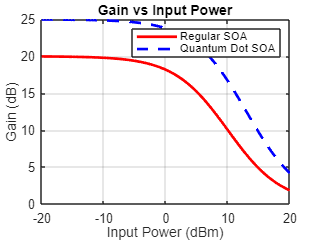

% Compare regular SOA vs. quantum dot SOA

% Define input power range (in dBm)
Pin_dBm = -20:0.5:20; 
Pin_mW = 10.^(Pin_dBm/10); % convert dBm to mW

% Parameters for Regular SOA
G0_reg = 20; % small-signal gain in dB
Psat_reg = 10; % saturation power in mW
NF_reg = 6; % noise figure in dB
BW_reg = 35; % bandwidth in nm

% Parameters for Quantum Dot SOA
G0_qd = 25; % small-signal gain in dB
Psat_qd = 20; % saturation power in mW
NF_qd = 3.5; % noise figure in dB
BW_qd = 60; % bandwidth in nm

% Gain model: Gain = G0 / (1 + Pin/Psat)
Gain_reg = G0_reg ./ (1 + Pin_mW / Psat_reg);
Gain_qd  = G0_qd  ./ (1 + Pin_mW / Psat_qd);

% Plot Gain vs Input Power
figure;
plot(Pin_dBm, Gain_reg, 'r', 'LineWidth', 2); hold on;
plot(Pin_dBm, Gain_qd, 'b--', 'LineWidth', 2);
xlabel('Input Power (dBm)');
ylabel('Gain (dB)');
title('Gain vs Input Power');
legend('Regular SOA', 'Quantum Dot SOA');
grid on;

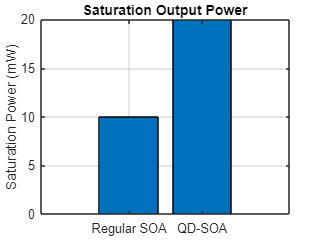


% Plot Saturation Output Power
figure;
bar([1 2], [Psat_reg Psat_qd]);
set(gca, 'xticklabel', {'Regular SOA', 'QD-SOA'});
ylabel('Saturation Power (mW)');
title('Saturation Output Power');
grid on;

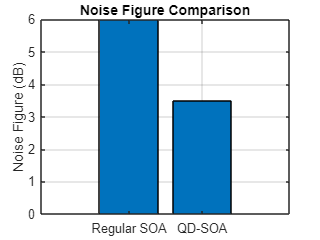


% Plot Noise Figure
figure;
bar([1 2], [NF_reg NF_qd]);
set(gca, 'xticklabel', {'Regular SOA', 'QD-SOA'});
ylabel('Noise Figure (dB)');
title('Noise Figure Comparison');
grid on;

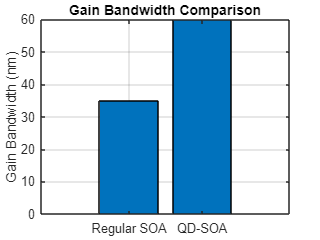


% Plot Gain Bandwidth
figure;
bar([1 2], [BW_reg BW_qd]);
set(gca, 'xticklabel', {'Regular SOA', 'QD-SOA'});
ylabel('Gain Bandwidth (nm)');
title('Gain Bandwidth Comparison');
grid on;